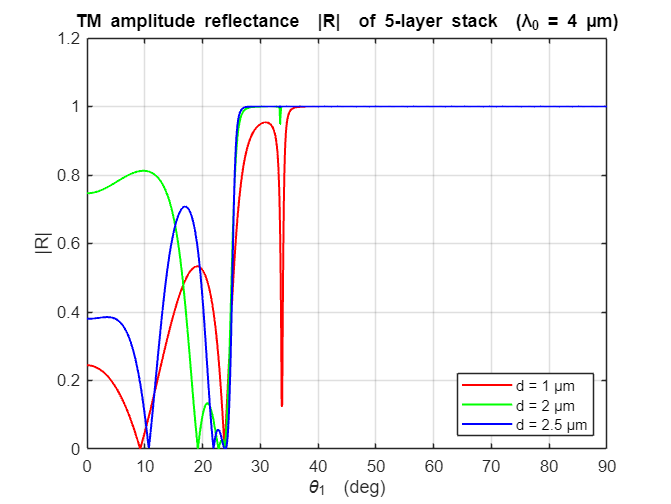



clear;   clc;

% ---------------------------- CONSTANTS -----------------------------
lambda0 = 4e-6;                
k0      = 2*pi/lambda0;        
eta0    = 376.730313668;       

n  = [3.4  1.5  3.4  1.5  3.4];      
d0 = 0.5e-6;                         

dChoices = [1 2 2.5]*1e-6;            
nAngles  = 1000;
thetaDeg = linspace( 1e-3 , 89.999 , nAngles );   % avoid exactly 0° & 90°
thetaRad = deg2rad(thetaDeg);


Rmag = zeros(numel(dChoices), nAngles);   % |R|
Tmag = zeros(numel(dChoices), nAngles);   % |T|

% ----------------- MAIN LOOP OVER THE THREE THICKNESSES --------------
for id = 1:numel(dChoices)
    d1 = dChoices(id);                        
    d  = [0  d1  d0  d1  0];                 
    
    % Loop over incidence angle
    for ia = 1:nAngles
        th1   = thetaRad(ia);                 
        kx    = k0*n(1)*sin(th1);            
        cosT  = zeros(size(n));              
        
        % Longitudinal (z) wavenumbers and cos θ_i
        kz = zeros(size(n));
        for ii = 1:numel(n)
            kz(ii)   =  sqrt( (k0*n(ii))^2 - kx^2 );
            cosT(ii) =  kz(ii)/(k0*n(ii));
        end
        
        % ----------------- TRANSFER-MATRIX PRODUCT -------------------
        M = eye(2);
        for ii = 1:(numel(n)-1)

            n_i  = n(ii);      n_ip1 = n(ii+1);
            eta_i   = eta0/n_i;
            eta_ip1 = eta0/n_ip1;

            % Fresnel reflection / transmission (TM)
            rTM = (eta_ip1*cosT(ii+1) - eta_i*cosT(ii)) / ...
                  (eta_ip1*cosT(ii+1) + eta_i*cosT(ii));
            tTM = (2*eta_ip1*cosT(ii)) / ...
                  (eta_ip1*cosT(ii+1) + eta_i*cosT(ii));

            Tmat = (1/tTM)*[ 1  rTM ; rTM  1 ];   

            if d(ii+1) > 0                        
                P = [ exp( 1j*kz(ii+1)*d(ii+1) )   0 ;
                      0                             exp(-1j*kz(ii+1)*d(ii+1)) ];
                M = M * Tmat * P;
            else
                M = M * Tmat;
            end
        end

        % ---------------- GLOBAL r and t  ---------------------------
        r =  M(2,1) / M(1,1);
        t =  1       / M(1,1);

        Rmag(id,ia) = abs(r);      % store |R|
        Tmag(id,ia) = abs(t);      % store |T|
        
        
    end
end

% -------------------------  PLOTS  -----------------------------------
figure('Color','w');
plot(thetaDeg, Rmag(1,:), 'r-' , ...
     thetaDeg, Rmag(2,:), 'g-' , ...
     thetaDeg, Rmag(3,:), 'b-' , 'LineWidth',1.2);
grid on;  xlabel('\theta_1  (deg)');  ylabel('|R|');
title('TM amplitude reflectance  |R|  of 5-layer stack  (λ_0 = 4 µm)');
legend('d = 1 µm','d = 2 µm','d = 2.5 µm','Location','SouthEast');
xlim([0 90]);

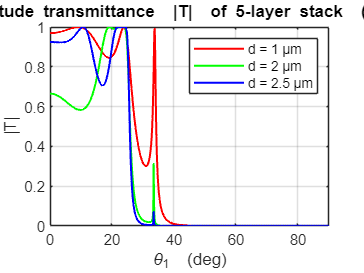


figure('Color','w');
plot(thetaDeg, Tmag(1,:), 'r-' , ...
     thetaDeg, Tmag(2,:), 'g-' , ...
     thetaDeg, Tmag(3,:), 'b-' , 'LineWidth',1.2);
grid on;  xlabel('\theta_1  (deg)');  ylabel('|T|');
title('TM amplitude transmittance  |T|  of 5-layer stack  (λ_0 = 4 µm)');
legend('d = 1 µm','d = 2 µm','d = 2.5 µm','Location','NorthEast');
xlim([0 , 90]) ;